# Explore Pokémon Cards Data

## Read Data

Converted Japanese Character to UTF-8 in Python. Import converted table `card30000_utf8.csv`.

opts = delimitedTextImportOptions("NumVariables", 41);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Var1", "Var2", "Var3", "cardId", "cardType", "name", "img", "regulation", "setNum", "setCount", "rarity", "dexNum", "dexClass", "height", "weight", "dexDesc", "author", "desc", "stage", "hp", "pType", "ability", "abilityDesc", "waza1Cost", "waza1Name", "waza1Damage", "waza1Desc", "waza2Cost", "waza2Name", "waza2Damage", "waza2Desc", "GXCost", "GXName", "GXDamage", "GXDesc", "weakType", "weakValue", "resistType", "resistValue", "escape", "spRule"];
opts.SelectedVariableNames = ["cardId", "cardType", "name", "img", "regulation", "setNum", "setCount", "rarity", "dexNum", "dexClass", "height", "weight", "dexDesc", "author", "desc", "stage", "hp", "pType", "ability", "abilityDesc", "waza1Cost", "waza1Name", "waza1Damage", "waza1Desc", "waza2Cost", "waza2Name", "waza2Damage", "waza2Desc", "GXCost", "GXName", "GXDamage", "GXDesc", "weakType", "weakValue", "resistType", "resistValue", "escape", "spRule"];
opts.VariableTypes = ["string", "string", "string", "double", "categorical", "string", "string", "categorical", "double", "double", "categorical", "double", "categorical", "double", "double", "string", "categorical", "string", "categorical", "double", "categorical", "string", "string", "string", "string", "categorical", "string", "string", "string", "categorical", "string", "string", "string", "categorical", "string", "categorical", "categorical", "categorical", "categorical", "double", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Var1", "Var2", "Var3", "name", "img", "dexDesc", "desc", "ability", "abilityDesc", "waza1Cost", "waza1Name", "waza1Desc", "waza2Cost", "waza2Name", "waza2Desc", "GXCost", "GXName", "GXDesc", "spRule"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "Var2", "Var3", "cardType", "name", "img", "regulation", "rarity", "dexClass", "dexDesc", "author", "desc", "stage", "pType", "ability", "abilityDesc", "waza1Cost", "waza1Name", "waza1Damage", "waza1Desc", "waza2Cost", "waza2Name", "waza2Damage", "waza2Desc", "GXCost", "GXName", "GXDamage", "GXDesc", "weakType", "weakValue", "resistType", "resistValue", "spRule"], "EmptyFieldRule", "auto");

% Read Japanese char
% opts = setvaropts(opts, 'Encoding', 'UTF-8');

% Import the data
t = readtable("/Users/solgaleo/Developer/GitHub/PTCG-database/exploratory/card30000_utf8.csv", opts, 'Encoding', "UTF-8")

t = 7859×38 table
    cardId    cardType        name                                      img                                  regulation    setNum    setCount      rarity       dexNum        dexClass         height    weight                                      dexDesc                                          author         desc    stage     hp       pType      ability    abilityDesc             waza1Cost               waza1Name       waza1Damage                                        waza1Desc                                                     waza2Cost             


clear opts

## Pokémon names

Pikachu is no doubt the No. 1 pokémon.

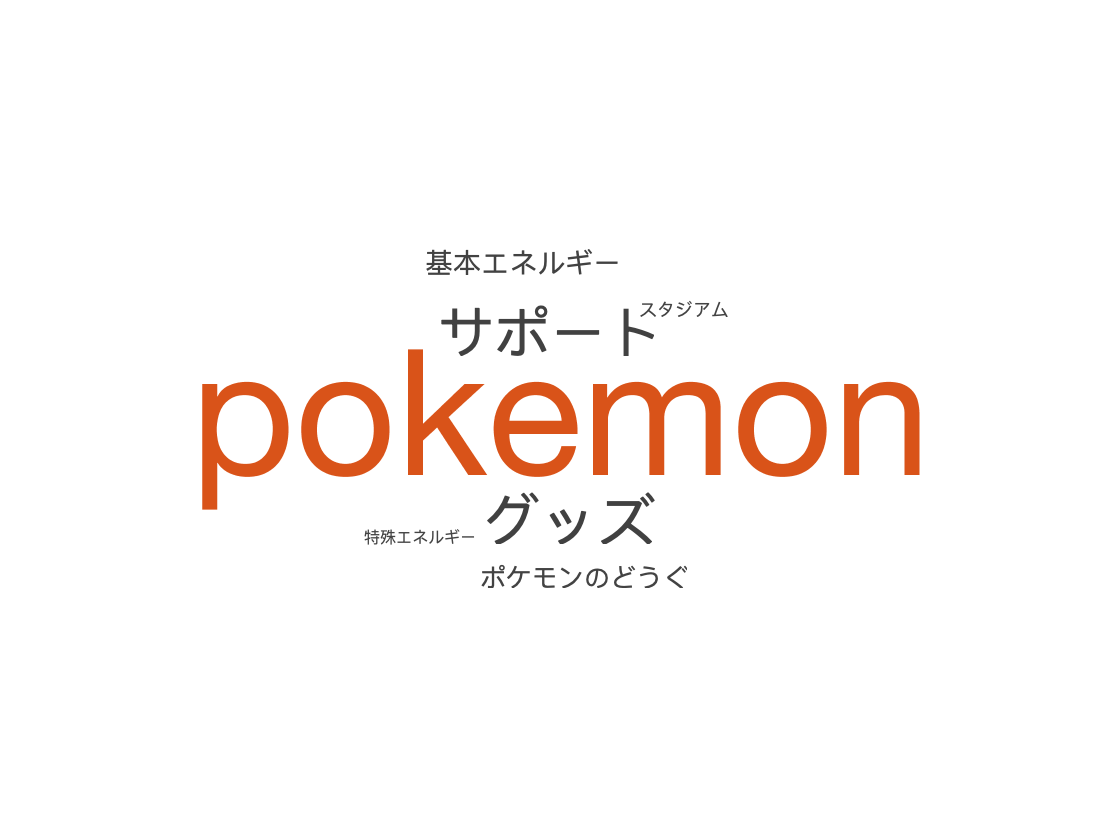

wordcloud(t.cardType);

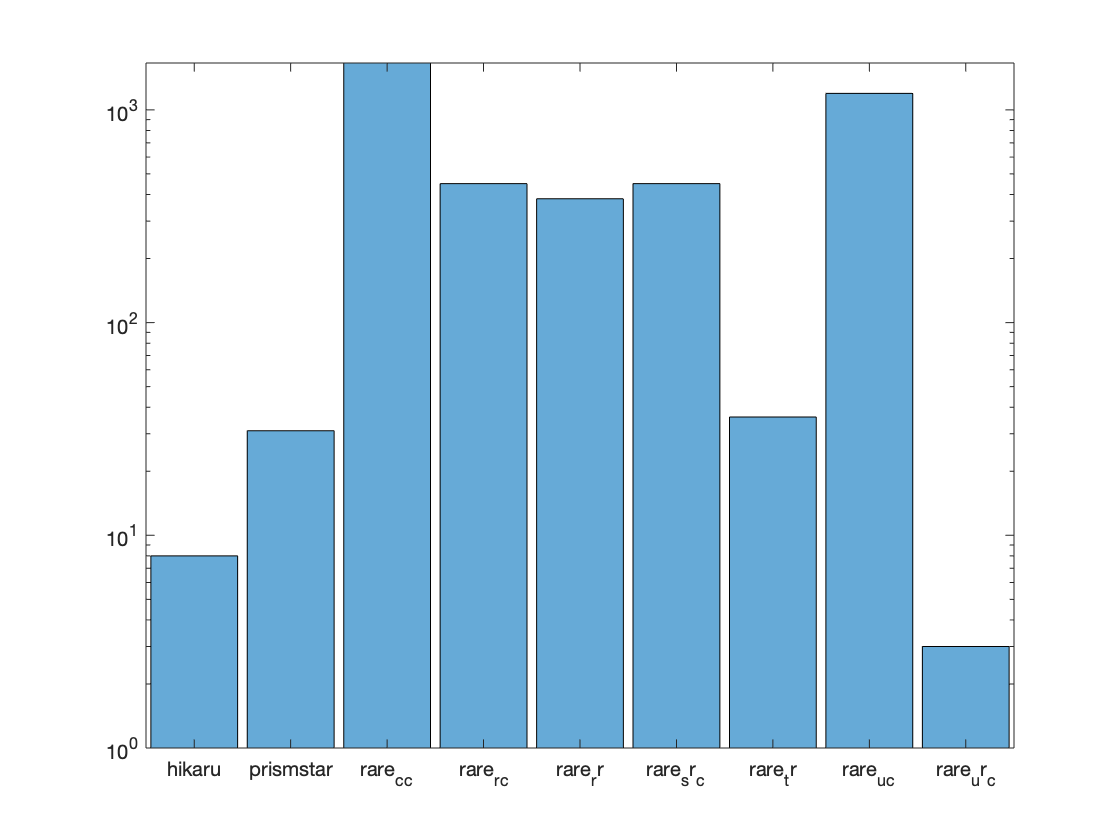

tWord = t;
tWord.nameCat = categorical(tWord.name);
% remove basic energies
[ii,jj,kk]=unique(t.name);
freq=accumarray(kk,1);
out=[ii num2cell(freq)];
out = out(str2double(out(:,2))>20,:);
energies = categorical(out(13:21,1));
tWord = tWord(~ismember(tWord.nameCat, energies),:);
wordcloud(tWord.nameCat);

## Regulation

Apart from promos, SM12a and SM8b print most cards.

figure;
histogram(t.regulation);

Rarity

figure;
histogram(t.rarity);
set(gca,'yscale','log');

Illustrator

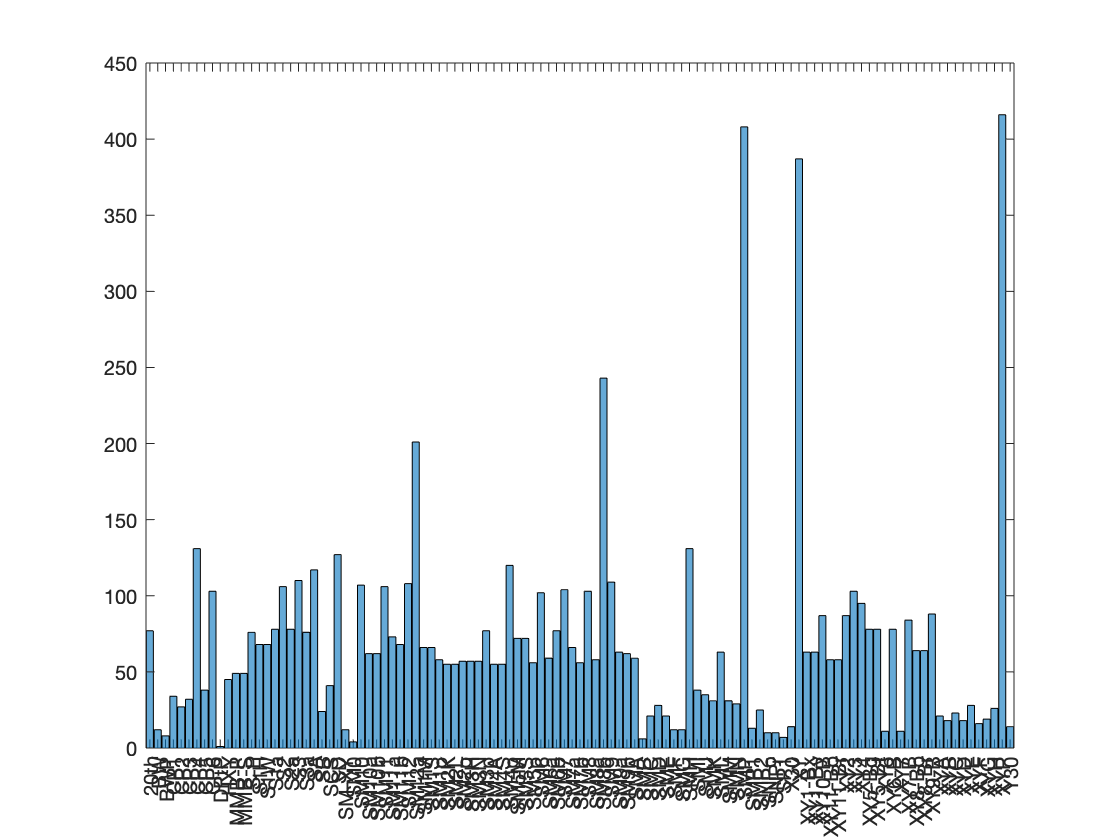

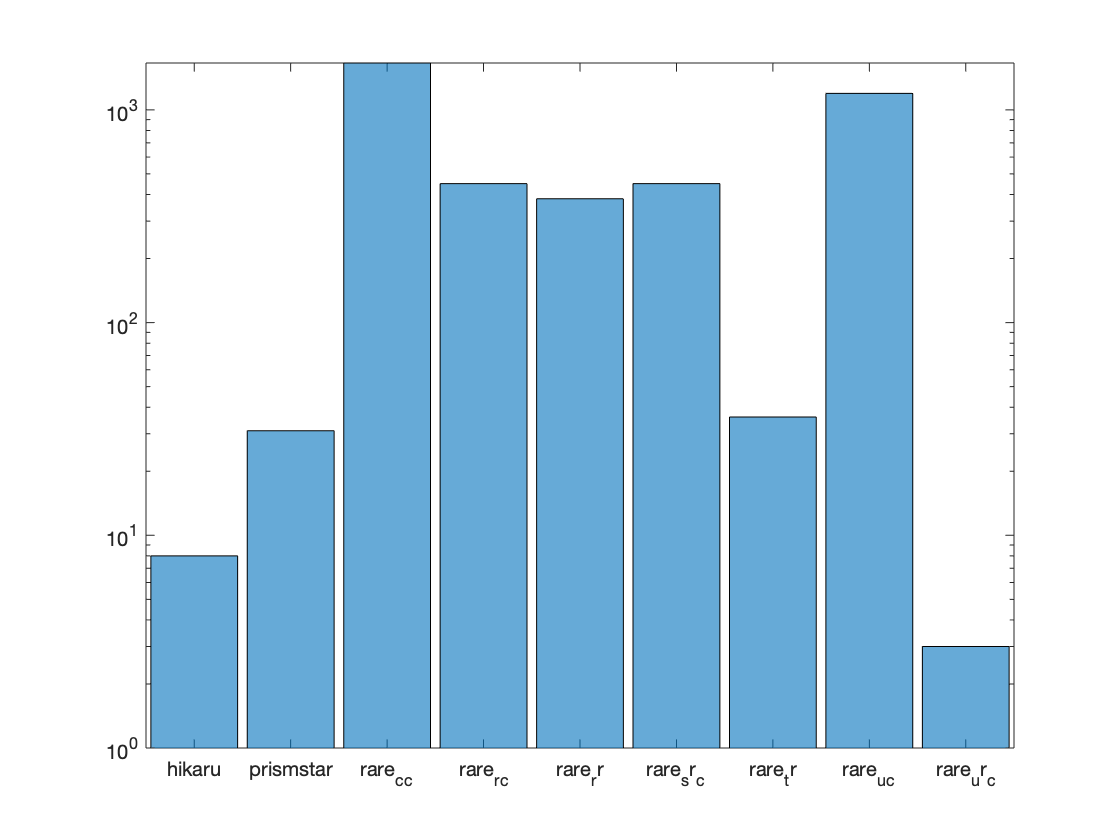

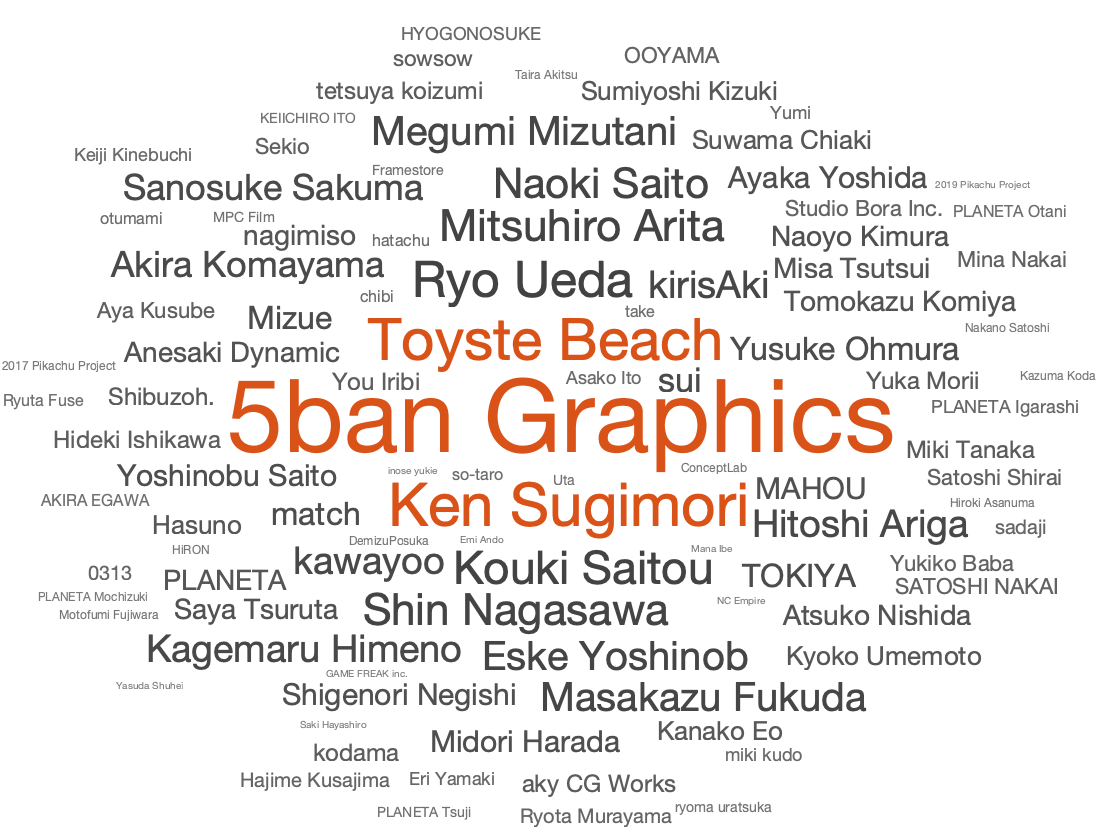

figure;
wordcloud(t.author);

## Split and Organize Data by Regulation

tSorted = sortrows(t, ["cardId", "regulation", "setNum"]);